ref2D_ray_rect_3.5MHz_600.mat


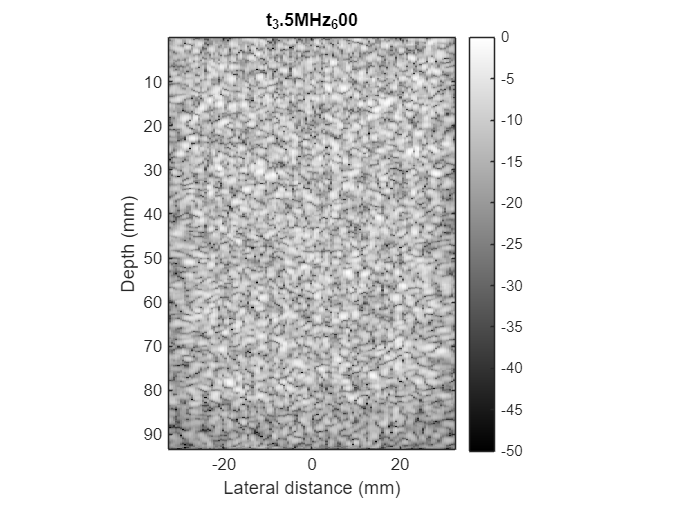

clearvars; close all; clc;
p=[600];
% p=[100];

for j=1:length(p)
n=['ref2D_ray_rect_3.5MHz_600.mat'];
load(n);
disp(n);

data=combined_sensor_data;
param.el_pos=positions;
param.c=c0;
param.fs=fs;
param.fc=tone_burst_freq;
param.t0=0;
param.fnumber=3;

param.save=false;

[rf,bm]=bf2(data,param,['ref2D_ray_rect_3.5MHz_',num2str(p(j))]);
end

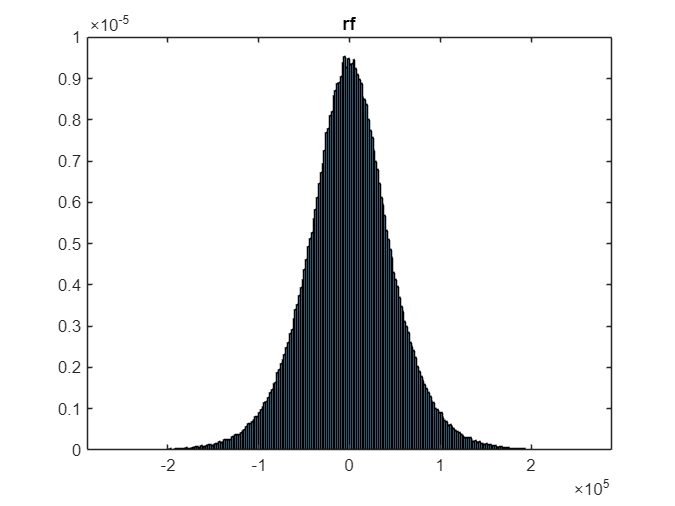

figure;histogram(rf, 'Normalization', 'pdf');title('rf');

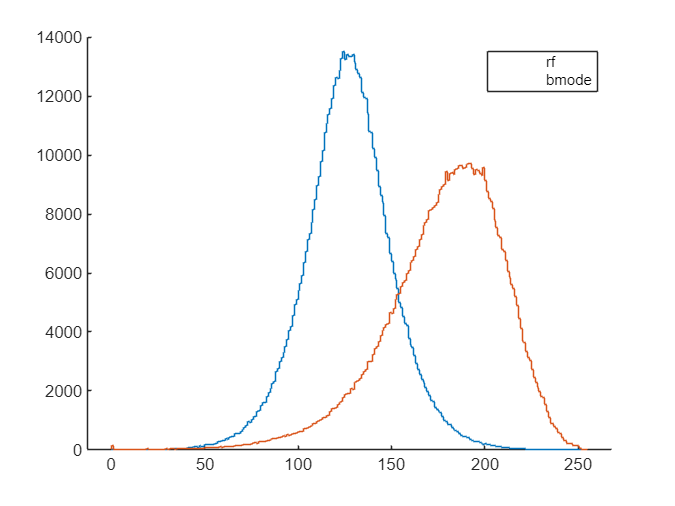

% figure;histogram(bm, 'Normalization', 'pdf');title('bmode');
% figure;histogram(abs(rf), 'Normalization', 'pdf');title('abs(rf)');
% figure;histogram(abs(bm), 'Normalization', 'pdf');title('abs(bmode)');

bm2=max(min(bm, 0), -50);
% figure;imagesc(bm); colorbar;clim([-50 0]);colormap gray;
figure;hold on;histogram(rescale(rf,0,255),DisplayStyle='stairs');%title('rf rescaled');
histogram(rescale(bm2,0,255),DisplayStyle='stairs');%title('bmode rescaled');
legend('rf','bmode');hold off;

function [rf,bm]=bf2(data,param,file_out)
data(1:500,:,:)=0;
fs = param.fs;
c0 = param.c;

% x = linspace(0,0.0384,128); x = x-mean(x);
% Nx=690;
% dx = 0.09e-3;
% % x=(1:128)*dx; %%% posiciones en x de la imagen
% % x = x-mean(x);
% x=linspace(0,Nx*dx,128);x=x-mean(x);
x=param.el_pos;

freq_vector = [param.fc];
for ii = 1:length(freq_vector)
    % freq = freq_vector(ii);
    %file_LP = ['SCOMP',num2str(freq),'MHz_nc10_0p08f2_ref80_doubleangle720'];
    %file_HP = ['SCOMP',num2str(freq),'MHz_nc10_0p08f2_ref400_doubleangle720'];
    % file_LP = ['SCOMP',num2str(freq),'MHz_nc10_samincBAatt80_doubleangle720'];
    % file_HP = ['SCOMP',num2str(freq),'MHz_nc10_samincBAatt400_doubleangle720'];



    %file_LP = 'PWEf1gaus_data_saminc3_80kPa';
    %file_HP = 'PWEf1gaus_data_saminc3_400kPa';

    fnumber = param.fnumber;

    % file_out = ['rf_fnum',num2str(fnumber),'_',file_HP];
    %file_out = ['rfLINEAR_',file_HP];

    %keyboard
    % load(file_in)
    z = (1:length(data))*(1/fs)*c0/2;
    for rr = 1:size(data,3)
        rf(:,:,rr) = bf_planewave_pwc((data(:,:,rr))',fs,fnumber,0,param);
    end
    rf=rf(1500:end,:);

    % [prop.h,prop.w]=size(rf);
    % prop.txf=param.fc;
    % prop.sf=param.fs;
    % prop.extra=1;
    % prop.nframes=1;
    % iq=process_IQ(rf,prop);
    % iq=squeeze(iq);
    % env_ps_data=hypot(iq(:,1),iq(:,2));

    env_ps_data = abs(hilbert(rf(:,:,1)));
    env_ps_data_norm = env_ps_data./max(env_ps_data(:));
    env_ps_data_norm_comp = 20*log10(env_ps_data_norm);
    bm=env_ps_data_norm_comp;
    figure;
    imagesc(x*1e3,z*1e3,env_ps_data_norm_comp);
    colormap gray; clim([-50 0]); colorbar; axis image;
    xlabel('Lateral distance (mm)');ylabel('Depth (mm)');
    title(file_out(14:end));

    %keyboard
    %rf1 = rf;
    % load(file_HP)
    % %rf2 = rf;
    % for rr = 1:size(rf_prebf,3)
    %     rf2(:,:,rr) = bf_planewave_pwc((rf_prebf(:,:,rr))',fs,fnumber,0);
    % end
    % env_ps_data = abs(hilbert(rf2(500:end,:)));
    % env_ps_data_norm = env_ps_data./max(env_ps_data(:));
    % env_ps_data_norm_comp = 20*log10(env_ps_data_norm);
    % figure; imagesc(env_ps_data_norm_comp); colormap gray; clim([-50 0])
    % 
    % %keyboard
    if param.save
        save(file_out,'c0','fs','rf','x','z');
    end
end
end


function ps_data = bf_planewave_pwc(sensor_data_kwave,fs,fnumber,steering_angle,param)

data = sensor_data_kwave';
% Nx=690;
% dx = 0.09e-3;
% % x=(1:128)*dx*Nx; %%% posiciones en x de la imagen
% % x = x-mean(x);
% x=linspace(0,Nx*dx,128);x=x-mean(x);
x=param.el_pos;
c = param.c;
%fs = 1/1.168831168831169e-08; % THIS WILL DEPEND ON THE SAMPLING FREQEUNCY. DOUBLE CHECK IN KWAVE
%fs = 1/8.348794063079777e-09; % up to third harmonic as well
tx_positions = x;


for j=1:length(x) %% Iterar en x

    %h1 = waitbar(j/length(x),h1,['Generando líneas... ' num2str(j) '/' num2str(length(x))]);

    for i=1:size(data,1) %% Iterar en z

        %%% Posición del punto en x,z

        x_point=x(j);
        z_point=c*(i/fs)/2;
        z_rx=0;


        %%% Calcular retardos
        ang = steering_angle*pi/180;
        d_ec=z_point*cos(ang)+x_point*sin(ang);
        tau=(d_ec+sqrt(z_point^2+(x_point-tx_positions).^2))/c;

        %%% Calcular muestras (no se usa interpolación)

        muestra=round((tau)*fs);
        muestra(muestra<=0)=1;
        muestra(muestra>size(data,1))=1;
        ind=muestra+size(data,1)*(0:size(muestra,2)-1); %Indexación linear
        values=data(ind);

        %%% Sumar valores solo de la apertura
        %F = 3;
        F = fnumber;
        a=z_point/(2*F);
        liminf=x_point-a;
        limsup=x_point+a;
        apodization=(tx_positions<limsup & tx_positions>liminf);

        ps_data(i,j,1)=sum(apodization*values');

    end
    %keyboard


    % env_ps_data = abs(hilbert(ps_data(500:end,:)));
    % env_ps_data_norm = env_ps_data./max(env_ps_data(:));
    % env_ps_data_norm_comp = 20*log10(env_ps_data_norm);
    % figure; imagesc(env_ps_data_norm_comp); colormap gray; clim([-50 0])

end
end